Show how we can add together several shorter exposures -- even with camera motion -- to simulate a single longer exposure

First, set up a default scenario

ieInit;
useScene = sceneMap("Stanford Bunny"); % Select desired scene
useScenario = ivScenario(useScene);

% ivScenario has defaults, but we can over-ride them
useScenario.exposureTime = 0.001;% in seconds
useScenario.clipLength = 0.05;% Long Exposure
useScenario.raysPerPixel = 1024;
useScenario.fastPreview = 1;% divide rays & rez for previewing

% Save short exposure for later use
shortExposure = useScenario.exposureTime;

% calculate how many frames we need to add together
numFrames = round(useScenario.clipLength / useScenario.exposureTime);

% If we have the bunny, start to test object motion
if isequal(useScenario.sceneName, 'bunny')
    ourScene.allowObjectMotion = true;
    ourScene.objectMotion = {{'Bunny_O', [2 0 0], [0 0 0]}};
    % NOTE: Need to use a cpu version of pbrt for this case
end

Now we can modify settings or accept the default, and then create our video clips

sceneVideoClip(useScenario); % multi-capture

[INFO]: Read 2 materials and 0 textures.
[INFO]: Attribute processing: 
[INFO]: Identified 1 assets; parsed up to line 9

----- Summary of recipe: bunny

               index      material        positions (m)           sizes (m)     
               _____    ____________    __________________    __________________

    Bunny_O      4      {'BunnyMat'}    {'0.00 0.00 1.00'}    {'0.12 0.12 0.10'}

From [0.00, 0.000000, 0.000000] to [0.00, 0.000000, 1.000000] up [0.00, 1.000000, 0.000000]
Film diagonal not used for pinhole and human eye
Film diagonal not used for pinhole and human eye
Elapsed time is 2.540577 seconds.
[INFO]: Uploading data:
[INFO]: Sent 1,391 bytes  received 10,968 bytes  24,718.00 bytes/sec
[INFO]: Data uploaded successfully.
[INFO]: USE Docker: docker  --context remote-orange exec -it  pbrt-cpu-djc441 sh -c " pbrt  --o

% Single (longer) capture
useScenario.exposureTime = useScenario.clipLength;
sceneVideoClip(useScenario);

[INFO]: Read 2 materials and 0 textures.
[INFO]: Attribute processing: 
[INFO]: Identified 1 assets; parsed up to line 9

----- Summary of recipe: bunny

               index      material        positions (m)           sizes (m)     
               _____    ____________    __________________    __________________

    Bunny_O      4      {'BunnyMat'}    {'0.00 0.00 1.00'}    {'0.12 0.12 0.10'}

From [0.00, 0.000000, 0.000000] to [0.00, 0.000000, 1.000000] up [0.00, 1.000000, 0.000000]
Film diagonal not used for pinhole and human eye
Film diagonal not used for pinhole and human eye
Elapsed time is 2.851797 seconds.
[INFO]: Uploading data:
[INFO]: Sent 1,394 bytes  received 10,968 bytes  8,241.33 bytes/sec
[INFO]: Data uploaded successfully.
[INFO]: USE Docker: docker  --context remote-orange exec -it  pbrt-cpu-djc441 sh -c " pbrt  --ou

By default, results are in local/synthetic-scene-tests, labeled with their exposure time in ms,  and the frame number in the multi-frame sequence.

We call sceneSynthesize both on the multiple exposures to sum them up,  and on the longer exposure(s) which we want to compare. 

We do this even for the case of a single longer exposure because it also does some baseline processing of the raw scene.

Typically the "start" frame is 001, so we've currently hard-coded that.

sceneSynthesize(fullfile(ivDirGet('computed'), ...
    sprintf('%s*-%03d.exr', useScene, round(shortExposure * 1000))),numFrames);
sceneSynthesize(fullfile(ivDirGet('computed'), ...
    sprintf('%s*-%03d.exr', useScene, round(useScenario.clipLength * 1000))),1);

NOTE: We need to move the generated files to generated, or put them there right away:)

Now we can compare the synthesized scene(s).

sceneHomeDir =  ivDirGet('computed');
% scene names have 3 codes:
% * exposureTime in ms
% * first frame in series (typically 001)
% * last frame in series (typically 001 or numFrames)
[sensorSingle, sensorMulti] = sceneCompare( ...
    fullfile(sceneHomeDir,sprintf('%s-%03d-%03d-%03d.mat',useScene, ...
        round(shortExposure*1000), 1, numFrames)), ...
    fullfile(sceneHomeDir, sprintf('%s-%03d-%03d-%03d.mat',useScene, ...
        round(useScenario.exposureTime*1000),1,1)), useScenario.exposureTime);

Denoised in: 23.833
Denoised in: 21.502


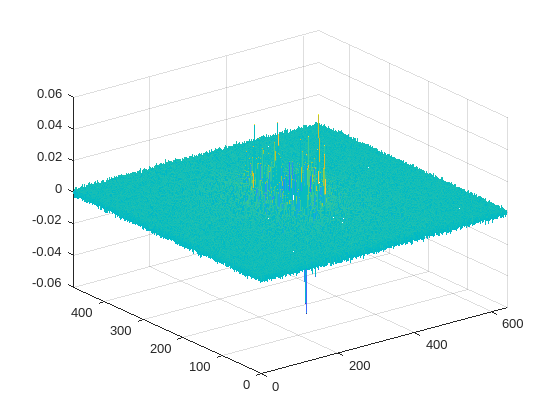

% Show results
mesh(sensorSingle.data.volts - sensorMulti.data.volts);

[ssimVal, ssimMap] = ssim(sensorSingle.data.volts, sensorMulti.data.volts);
fprintf('%f\n',ssimVal)

0.995561


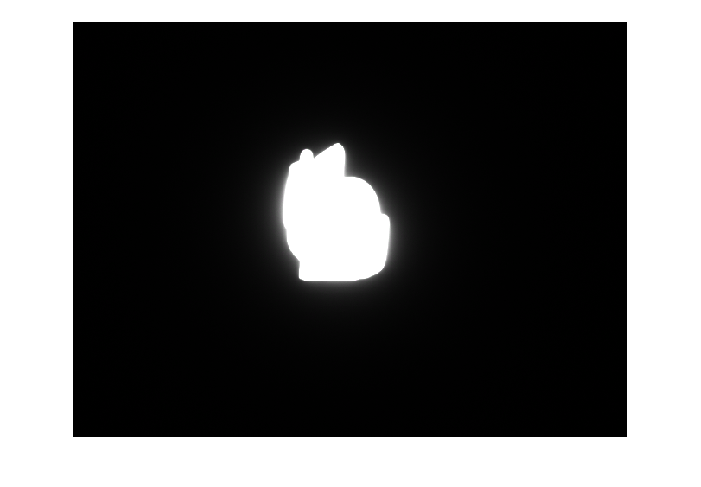

imshowpair(sensorSingle.data.volts,sensorMulti.data.volts,'falsecolor');

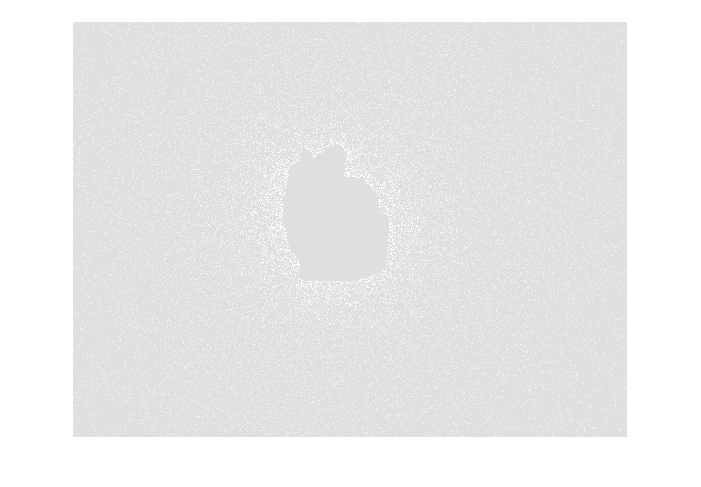

imshow(histeq(sensorSingle.data.volts - sensorMulti.data.volts));

function useScene = sceneMap(sceneLabel)
switch sceneLabel
    case 'Pavilion-Day'
        useScene = 'pavilion-day';
    case 'Paviioon-Night'
        useScene = 'pavilion-night';
    case "MacBeth Checker"
        useScene = 'MacBethChecker';
    case "Cornell Box"
        useScene = 'cornell_box';
    case 'Stanford Bunny'
        useScene = 'bunny';
end
end